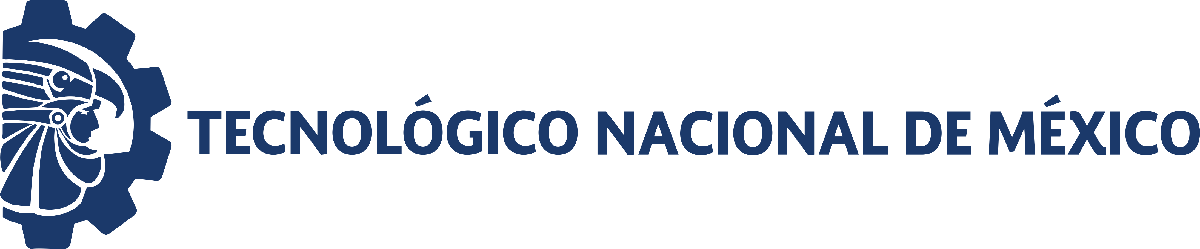                                 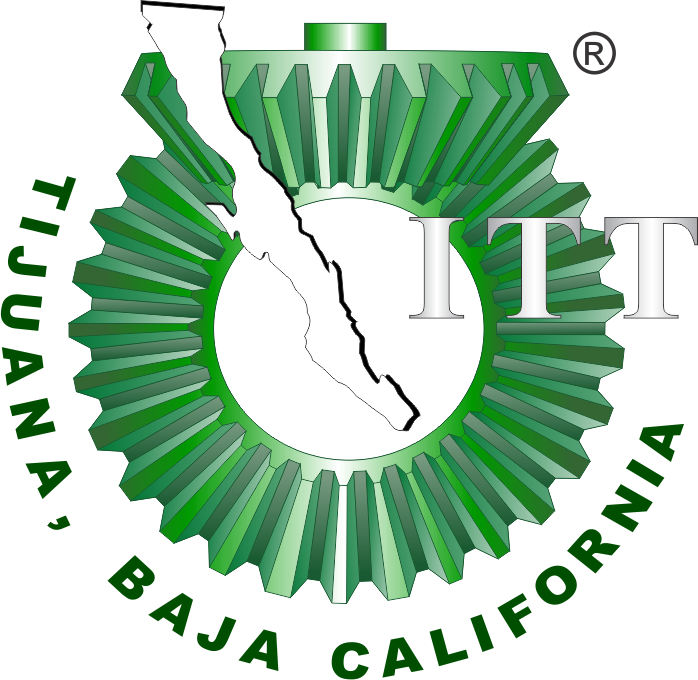

# Práctica 3: Algoritmo de regresion no lineal

Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[Foto]

Nombre del alumno: **Mendivil Ramirez Frida Daniela**

Número de control: 20211983

Correo institucional: **L20211983@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## **Simulation Data**

clc; clear; close all

sys = readmatrix('data (2).csv');
to = round(sys(:,1));
x1 = sys(:,2); 
x2 = sys(:,3); 
xo = mean([x1, x2], 2); % Calcula la media

T = array2table([to, x1, x2, xo], 'VariableNames',{'time','Sample 1','Sample 2','Mean'}); 
disp(T)

    time     Sample 1      Sample 2        Mean   
    ____    __________    __________    __________

      0     6.7923e+07    6.7772e+07    6.7847e+07
      8     1.3379e+08     1.027e+08    1.1825e+08
     16     4.3319e+08    3.3628e+08    3.8474e+08
     24     8.9155e+08    8.6832e+08    8.7993e+08
     32     9.5773e+08    9.8052e+08    9.6912e+08
     40     9.8148e+08    9.9791e+08    9.8969e+08
     48     9.9525e+08    9.9276e+08      9.94e+08
     56     9.8971e+08         1e+09    9.9485e+08
     64          1e+09    9.7521e+08     9.876e+08
     72     9.9383e+08    9.7827e+08    9.8605e+08



### Function

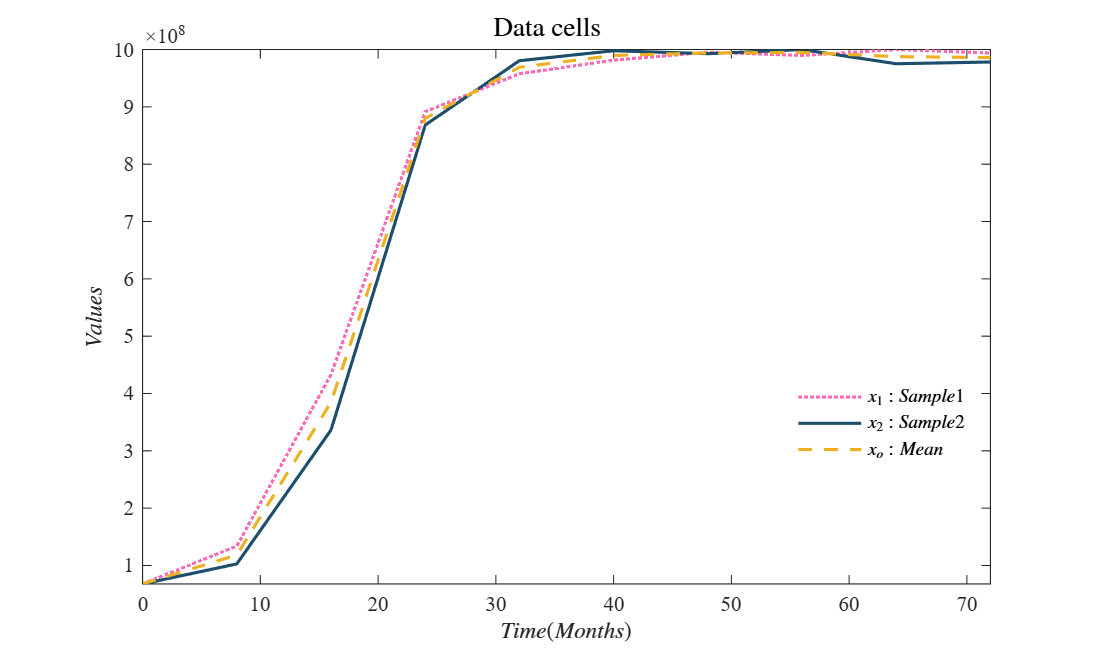

figure;
set(figure(), 'Color' , 'w')
set(gcf, 'Units', 'Centimeters', 'Position', [2,2,20,12])
set (gca, 'FontName' , 'Times New Roman'); fontsize(10, 'points') 
    
hold on; box on; grid off
    
plot (to,x1,':', 'LineWidth',1.5, 'Color', [1, 0.41, 0.71])
plot(to,x2,' -', 'LineWidth',1.5, 'Color', [0.11,0.30,0.42])
plot(to,xo,' --', 'LineWidth',1.5, 'Color', [0.93,0.69,0.13])
    xlabel('$Time (Months)$', 'Interpreter', 'Latex' )
    ylabel('$Values$', 'Interpreter', 'Latex' )
    L= legend('$x_1: Sample 1$','$x_2: Sample 2$','$x_o: Mean$');
       set(L,'Interpreter','Latex','Location','Best','Box','off')
    xlim([min(to) max(to)])
    ylim([min([x1; x2; xo]) max([x1; x2; xo])])
   ttl = 'Data cells'; sgtitle(ttl,'Interpreter','Latex')
   exportgraphics(gcf,'data cells.pdf', 'ContentType','vector')

## Logistic growth law

xmax = max(xo);
b=1/xmax;
k0=1E-3;
mdl_alometric = logistic(to,xo,k0,b);


Parameter b: 1.0052e-09
Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student value:2.2622
R-squared:0.9757
Corrected AIC (n/pars < 40):387.6464

    Parameters    Estimate       SE          MoE             CI95             pvalue  
    __________    ________    _________    ________    _________________    __________

       "k"        0.16158     0.0095842    0.021681    0.1399    0.18327    4.0727e-08



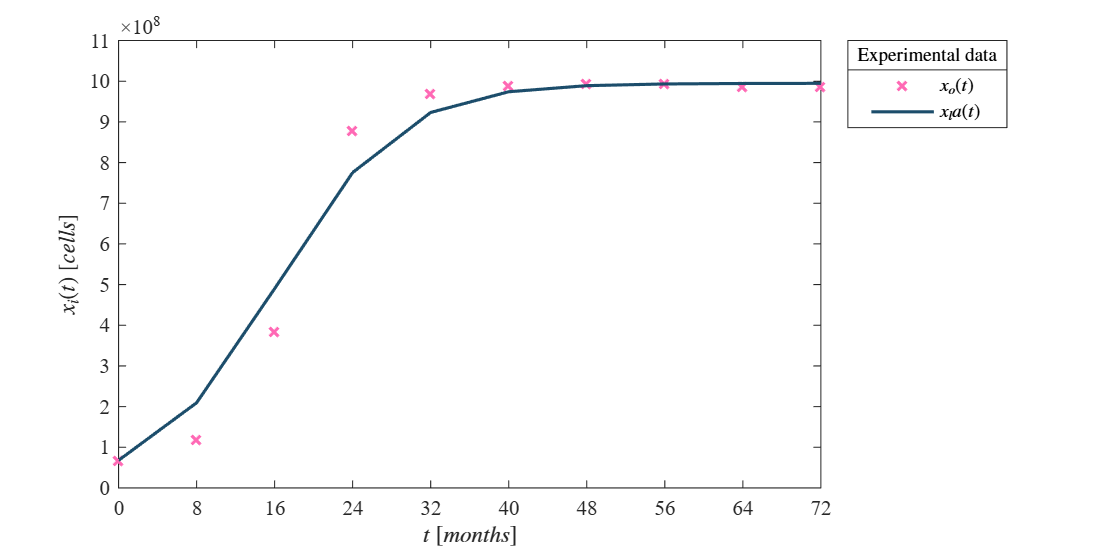

xla = mdl_alometric.Fitted; 
plotfit(to,xo,xla);

#### Nonlinear regression algorithm: logistic growth law

function mdl= logistic(to,xo,k0,b)
    function xi = model (k,t)
        dt = 1E-1;
        time= (0:dt:max(t))';
        n = round(max(t)/dt);
        x= zeros(length(time),1); x(1) = xo(1);

        for i = 1:n
            fx = f(x(i));
            xn = x(i) + fx*dt;
            fxn = f(xn);
            x(i+1) = x(i) + (fx+fxn)*dt/2;
        end

        function dx = f(x)
            dx = k*x*(1-b*x);
        end

        xi = zeros(length(t),1);
        for j = 1:length(t)
            l = abs(time-t(j)) < 1E-9;
            xi(j) = x(l);
        end
    end
        mdl = fitnlm(to,xo,@model,k0);

       Estimate = table2array(mdl.Coefficients(:,1));
       SE = table2array(mdl.Coefficients(:,2));
       pvalue = table2array(mdl.Coefficients(:,4));
       alpha = 0.05;
       CI95 = coefCI(mdl,alpha);
       dof = mdl.DFE;
       tval = tinv(1 - alpha/2,dof);
       MoE = SE*tval;
       Parameters = "k";
       Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

       fprintf(['\nParameter b: ', num2str(b)])
       fprintf(['\nSample size (n): ', num2str(numel(xo))])
       fprintf(['\nParameters to be estimated (pars): ', num2str(numel(k0))])
       fprintf(['\nDegrees of freedom: ', num2str(dof)])
       fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
       fprintf(['\nt-Student value:', num2str(tval)])
       fprintf(['\nR-squared:', num2str(mdl.Rsquared.Ordinary)])
       fprintf(['\nCorrected AIC (n/pars < 40):', num2str(mdl.ModelCriterion.AIC), '\n\n'])
       disp(Results)
end

### Alometric sphere growth law

xmax = max(xo);
b=nthroot(1/xmax,3);
k0=1E-3;
mdl_alometric = alometric(to,xo,k0,b);


Parameter b: 0.0010017
Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student value:2.2622
R-squared:0.91801
Corrected AIC (n/pars < 40):399.8094

    Parameters    Estimate      SE       MoE            CI95            pvalue  
    __________    ________    ______    ______    ________________    __________

       "k"         228.81     31.385    70.999    157.82    299.81    4.6116e-05



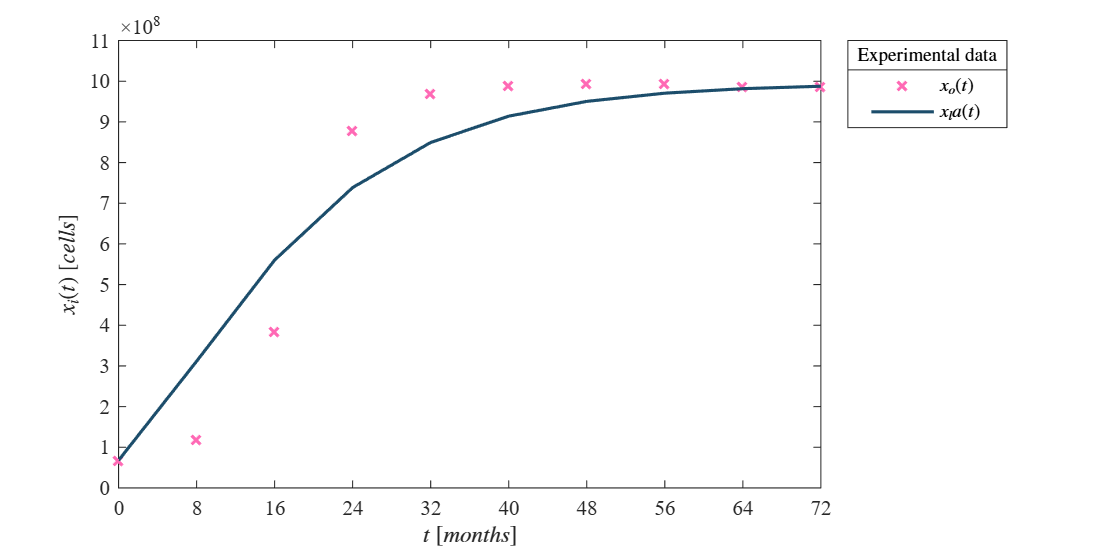

xla = mdl_alometric.Fitted; 
plotfit(to,xo,xla);

#### Nonlinear regression algorithm: alometric

function mdl= alometric(to,xo,k0,b)
    function xi = model (k,t)
        dt = 1E-1;
        time= (0:dt:max(t))';
        n = round(max(t)/dt);
        x= zeros(length(time),1); x(1) = xo(1);

        for i = 1:n
            fx = f(x(i));
            xn = x(i) + fx*dt;
            fxn = f(xn);
            x(i+1) = x(i) + (fx+fxn)*dt/2;
        end

        function dx = f(x)
            dx = k*x^(2/3)*(1-b*x^(1/3));
        end

        xi = zeros(length(t),1);
        for j = 1:length(t)
            l = abs(time-t(j)) < 1E-9;
            xi(j) = x(l);
        end
    end
        mdl = fitnlm(to,xo,@model,k0);

       Estimate = table2array(mdl.Coefficients(:,1));
       SE = table2array(mdl.Coefficients(:,2));
       pvalue = table2array(mdl.Coefficients(:,4));
       alpha = 0.05;
       CI95 = coefCI(mdl,alpha);
       dof = mdl.DFE;
       tval = tinv(1 - alpha/2,dof);
       MoE = SE*tval;
       Parameters = "k";
       Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

       fprintf(['\nParameter b: ', num2str(b)])
       fprintf(['\nSample size (n): ', num2str(numel(xo))])
       fprintf(['\nParameters to be estimated (pars): ', num2str(numel(k0))])
       fprintf(['\nDegrees of freedom: ', num2str(dof)])
       fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
       fprintf(['\nt-Student value:', num2str(tval)])
       fprintf(['\nR-squared:', num2str(mdl.Rsquared.Ordinary)])
       fprintf(['\nCorrected AIC (n/pars < 40):', num2str(mdl.ModelCriterion.AIC), '\n\n'])
       disp(Results)
end

### Alometric fractal growth law

xmax = max(xo);
b=nthroot(1/xmax,4);
k0=1E-3;
mdl_GompertzSim = alometricfractal(to,xo,k0,b);


Parameter b: 0.0056307
Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student value:2.2622
R-squared:0.92352
Corrected AIC (n/pars < 40):399.1135

    Parameters    Estimate      SE       MoE            CI95            pvalue  
    __________    ________    ______    ______    ________________    __________

       "k"         56.982     7.4297    16.807    40.175    73.789    3.0955e-05



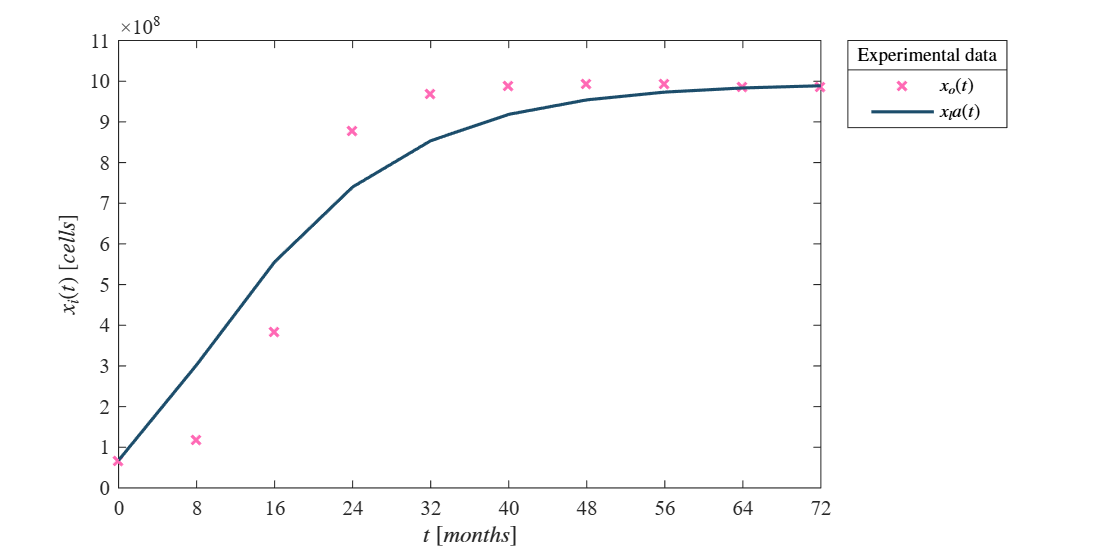

xla = mdl_GompertzSim.Fitted; 
plotfit(to,xo,xla);

#### Nonlinear regression algorithm: alometric fractal

function mdl= alometricfractal(to,xo,k0,b)
    function xi = model (k,t)
        dt = 1E-1;
        time= (0:dt:max(t))';
        n = round(max(t)/dt);
        x= zeros(length(time),1); x(1) = xo(1);

        for i = 1:n
            fx = f(x(i));
            xn = x(i) + fx*dt;
            fxn = f(xn);
            x(i+1) = x(i) + (fx+fxn)*dt/2;
        end

        function dx = f(x)
            dx = k*x^(3/4)*(1-b*x^(1/4));
        end

        xi = zeros(length(t),1);
        for j = 1:length(t)
            l = abs(time-t(j)) < 1E-9;
            xi(j) = x(l);
        end
    end
        mdl = fitnlm(to,xo,@model,k0);

       Estimate = table2array(mdl.Coefficients(:,1));
       SE = table2array(mdl.Coefficients(:,2));
       pvalue = table2array(mdl.Coefficients(:,4));
       alpha = 0.05;
       CI95 = coefCI(mdl,alpha);
       dof = mdl.DFE;
       tval = tinv(1 - alpha/2,dof);
       MoE = SE*tval;
       Parameters = "k";
       Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

       fprintf(['\nParameter b: ', num2str(b)])
       fprintf(['\nSample size (n): ', num2str(numel(xo))])
       fprintf(['\nParameters to be estimated (pars): ', num2str(numel(k0))])
       fprintf(['\nDegrees of freedom: ', num2str(dof)])
       fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
       fprintf(['\nt-Student value:', num2str(tval)])
       fprintf(['\nR-squared:', num2str(mdl.Rsquared.Ordinary)])
       fprintf(['\nCorrected AIC (n/pars < 40):', num2str(mdl.ModelCriterion.AIC), '\n\n'])
       disp(Results)
end

### Gompertz normal growth law

xmax = max(xo);
b=(1/log(xmax));
k0=1E-3;
mdl_GompertzSim = Gompertz(to,xo,k0,b);


Parameter b: 0.048267
Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student value:2.2622
R-squared:0.9385
Corrected AIC (n/pars < 40):396.9343

    Parameters    Estimate      SE         MoE            CI95            pvalue  
    __________    ________    _______    _______    ________________    __________

       "k"         1.9245     0.21469    0.48566    1.4389    2.4102    8.8198e-06



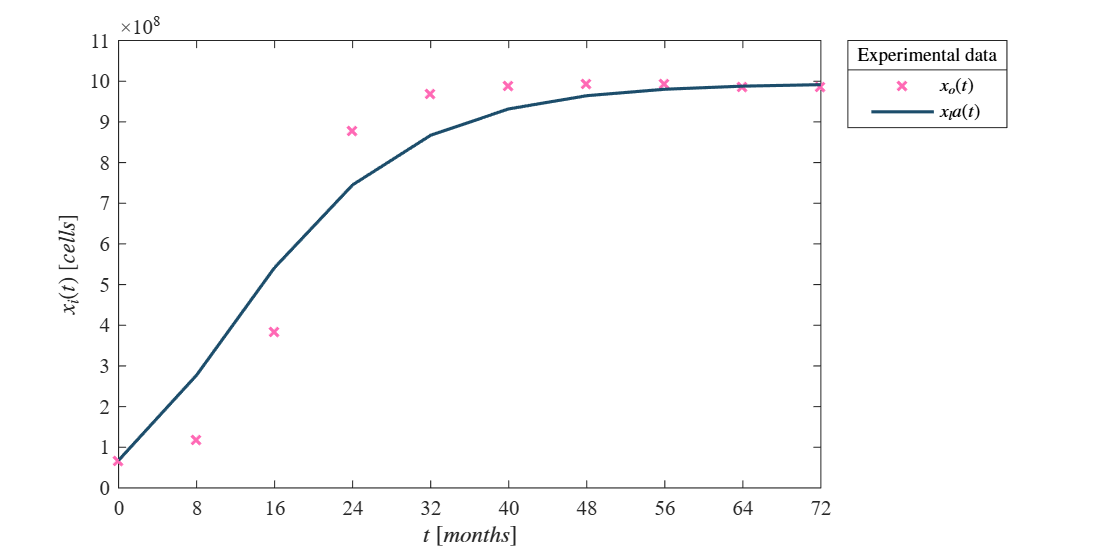

xla = mdl_GompertzSim.Fitted; 
plotfit(to,xo,xla);

#### Nonlinear regression algorithm: Gompertz normal

function mdl= Gompertz(to,xo,k0,b)
    function xi = model (k,t)
        dt = 1E-1;
        time= (0:dt:max(t))';
        n = round(max(t)/dt);
        x= zeros(length(time),1); x(1) = xo(1);

        for i = 1:n
            fx = f(x(i));
            xn = x(i) + fx*dt;
            fxn = f(xn);
            x(i+1) = x(i) + (fx+fxn)*dt/2;
        end

        function dx = f(x)
            dx = k*x*(1-b*log(x));
        end

        xi = zeros(length(t),1);
        for j = 1:length(t)
            l = abs(time-t(j)) < 1E-9;
            xi(j) = x(l);
        end
    end
        mdl = fitnlm(to,xo,@model,k0);

       Estimate = table2array(mdl.Coefficients(:,1));
       SE = table2array(mdl.Coefficients(:,2));
       pvalue = table2array(mdl.Coefficients(:,4));
       alpha = 0.05;
       CI95 = coefCI(mdl,alpha);
       dof = mdl.DFE;
       tval = tinv(1 - alpha/2,dof);
       MoE = SE*tval;
       Parameters = "k";
       Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

       fprintf(['\nParameter b: ', num2str(b)])
       fprintf(['\nSample size (n): ', num2str(numel(xo))])
       fprintf(['\nParameters to be estimated (pars): ', num2str(numel(k0))])
       fprintf(['\nDegrees of freedom: ', num2str(dof)])
       fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
       fprintf(['\nt-Student value:', num2str(tval)])
       fprintf(['\nR-squared:', num2str(mdl.Rsquared.Ordinary)])
       fprintf(['\nCorrected AIC (n/pars < 40):', num2str(mdl.ModelCriterion.AIC), '\n\n'])
       disp(Results)
end

### Gompertz simplificada growth law

xmax = max(xo);
b=(xmax);
k0=1E-3;
mdl_GompertzSim = GompertzSim(to,xo,k0,b);


Parameter b: 994854338
Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student value:2.2622
R-squared:0.9385
Corrected AIC (n/pars < 40):396.9343

    Parameters    Estimate       SE         MoE              CI95             pvalue  
    __________    ________    ________    ________    __________________    __________

       "k"        0.092892    0.010362    0.023441    0.06945    0.11633    8.8203e-06



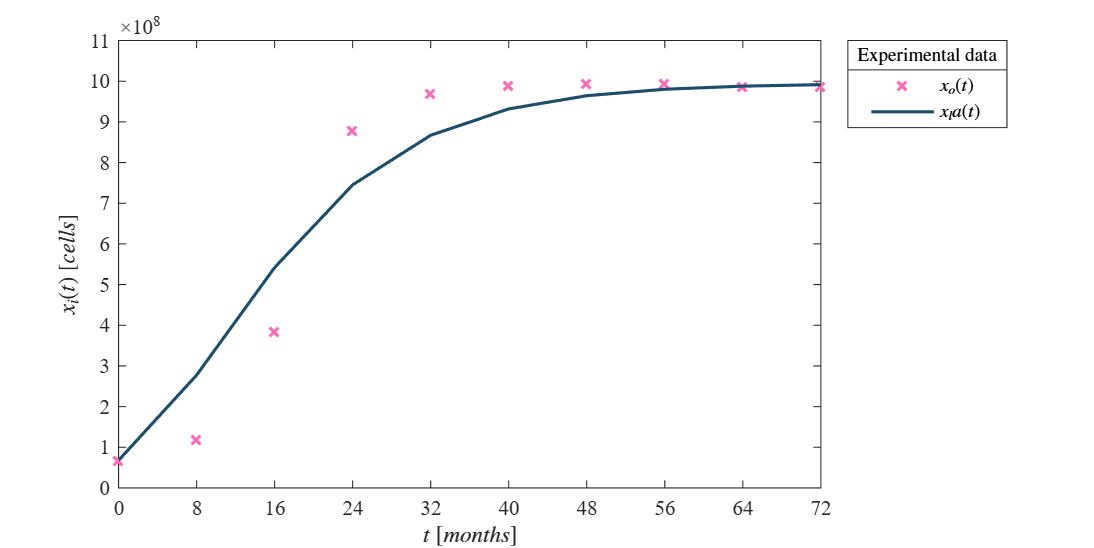

xla = mdl_GompertzSim.Fitted; 
plotfit(to,xo,xla);

#### Nonlinear regression algorithm: Gompertz normal

function mdl= GompertzSim(to,xo,k0,b)
    function xi = model (k,t)
        dt = 1E-1;
        time= (0:dt:max(t))';
        n = round(max(t)/dt);
        x= zeros(length(time),1); x(1) = xo(1);

        for i = 1:n
            fx = f(x(i));
            xn = x(i) + fx*dt;
            fxn = f(xn);
            x(i+1) = x(i) + (fx+fxn)*dt/2;
        end

        function dx = f(x)
            dx = k*x*log(b/(x));
        end

        xi = zeros(length(t),1);
        for j = 1:length(t)
            l = abs(time-t(j)) < 1E-9;
            xi(j) = x(l);
        end
    end
        mdl = fitnlm(to,xo,@model,k0);

       Estimate = table2array(mdl.Coefficients(:,1));
       SE = table2array(mdl.Coefficients(:,2));
       pvalue = table2array(mdl.Coefficients(:,4));
       alpha = 0.05;
       CI95 = coefCI(mdl,alpha);
       dof = mdl.DFE;
       tval = tinv(1 - alpha/2,dof);
       MoE = SE*tval;
       Parameters = "k";
       Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

       fprintf(['\nParameter b: ', num2str(b)])
       fprintf(['\nSample size (n): ', num2str(numel(xo))])
       fprintf(['\nParameters to be estimated (pars): ', num2str(numel(k0))])
       fprintf(['\nDegrees of freedom: ', num2str(dof)])
       fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
       fprintf(['\nt-Student value:', num2str(tval)])
       fprintf(['\nR-squared:', num2str(mdl.Rsquared.Ordinary)])
       fprintf(['\nCorrected AIC (n/pars < 40):', num2str(mdl.ModelCriterion.AIC), '\n\n'])
       disp(Results)
end

## solutions

function plotfit(to,xo,xla)

set(figure(), 'Color' , 'w')
set(gcf, 'Units', 'Centimeters','Position',[2,2,20,10])
set(gca,'FontName','Times New Roman')
fontsize(10,'points') 

hold on; box on; grid off;
plot(to,xo, 'x', 'LineWidth', 1.5, 'Color', [1, 0.41, 0.71])  
plot(to,xla, '-', 'LineWidth', 1.5, 'Color', [0.11,0.30,0.42]) 
xlabel('$t$ $[months]$','Interpreter', 'latex')
ylabel('$x_i(t)$ $[cells]$', 'Interpreter', 'latex')
L = legend('$x_o(t)$','$x_la(t)$');
set(L, 'Interpreter','latex','Location','NorthEastOutside')
title(L,'Experimental data')
xlim([0 72]); xticks(0:8:72)
ylim([0 11E8]); yticks (0:1E8:11E8)


    
end